%% intro
%clear all
rng("shuffle")
%rng(2,"twister")
d = 10;
m = 1;

fprintf('Distancia = %d, Medicion #%d\n', d, m);

Distancia = 10, Medicion #1


% tic
% 
% %% MAIN
% % Propiedades 
% 
% %Propiedades Transmisores
% % [X,Y,Z]
% trans = [1, 0.9, 1.05];  
% % Angulo en eje Z
% parameters.beta_i=90;                                     
% % Angulo en eje X 
% parameters.alpha_i=90;                                    
% %semi-ángulo de mitad de potencia del LED
% parameters.ang_rad = 60;          
% %número Lambertiano
% parameters.m= -log(2)/log(abs(cos(parameters.ang_rad*pi/180))); 
% 
% % Propiedades Receptores
% 
% % Area del PD
% parameters.Ap = 0.0013; %PDA36A        
% % Refraccion
% parameters.eta = 1.5;
% % FOV
% parameters.fov = 60;                  
% % Radio Esfera
% r = 0.05;                  
% % Angulo Esfera Eje X
% angle = 30;                 
% % Angulo Esfera en Radianes
% ele = 60*pi/180; 
% % Angulo Esfera en Grados
% eled = 60;                    
% 
% % Propiedades Paredes
% 
% %Area del elemento reflectante
% parameters.Aw=1;        
% %Coeficiente de reflexión del área reflectiva
% parameters.pw=0.6;                                   
% 
% % Propiedades Obstaculo
% % Ancho (Width)
% parameters.W=3;     
% % Altura (Height)
% parameters.H=0.95;    
% % Distribucion Uniforme 
% parameters.gv=[20 60];       
% % Distribucion Uniforme 
% parameters.fv=[0 5];                    
% % Epsilon
% parameters.es=5;                                        
% 
% % Propiedades Tunel
% % Largo
% parameters.X=3;               
% % Altura
% parameters.Y=2;                                        
% 
% % Propiedades Scattering
% % Distribucion Uniforme
% parameters.kr=[0.1 0.01];        
% % Distribucion Uniforme
% parameters.km=[0 10];                    
% % Distribucion Uniforme
% parameters.ks=parameters.kr+parameters.km;  
% % Numero de Scatters
% parameters.N=70;    
% 
% % Propiedades Simulacion
% % Tiempo
% parameters.t=5*10^-9;      
% % Velocidad de la Luz
% parameters.c=3*10^8 ;    
% %(0.25 nano segundo de muestreo, se disminuye para mayor numero de muestras)
% parameters.Sampling_time=0.25e-9;                      
% % Vector de Tiempo
% parameters.time=0:parameters.Sampling_time:35e-9;    
% % Redondeo
% parameters.time=round(parameters.time,12);   
% % Time Rise
% parameters.t_rise=0.5e-9;      
% % Time Low
% parameters.t_fall=1e-9;                                
% % Impulso PD
% parameters.h_led=10*(exp(-parameters.time/parameters.t_fall)-exp(-parameters.time/(parameters.t_rise))); 
% 
% 
% %% Calculo de H y h
% cX = trans(1)+(d/100);
% cY = 0.9;
% receiver_center = [cX, cY, 1.05];
% PD = PD_Position(receiver_center, r, angle, ele, eled);
% [Hmat, Final_response] = get_channel(PD, trans, parameters);
% 
% 
% 
% toc

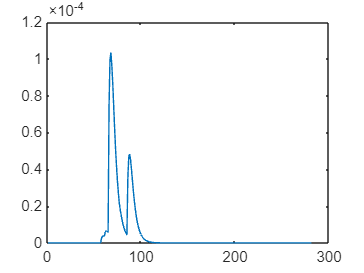

tic
% run("main_channel.m")
% 
% newresponse = zeros(1,800);
% newresponse(1:281) = Final_response(1:281);
% newresponse(300:451) = Final_response(1:152)*0.3;
% newresponse(600:751) = Final_response(1:152)*0.6;

load("Hp1.mat")
load("Hp2.mat")
load("Hp3.mat")
load("Hp4.mat")
load("Hp5.mat")



H = Hp5;

%H = Final_response;
%H = newresponse;
%H = [1, 0, 0, 0, 0];


figure
plot(H)



%% 1) Parameters
numSymbols      = 247170;    % Number of BPSK symbols
samplesPerSym   = 10;       % Oversampling factor
rolloff         = 0.25;    % Rolloff factor
span            = 6;       % Filter span in symbols
snrDB           = 20;      % SNR (dB)

% Raised Cosine Filter
rcFilter = rcosdesign(rolloff, span, samplesPerSym, 'sqrt');
filtLen  = length(rcFilter); 
filtDelay= (filtLen - 1)/2;  % Group delay in samples

% Example channel impulse response
% Make it short to highlight the effect of zero-forcing
h_est = H; 

%% 2) Transmitter
% Generate random bits
txBits = randi([0,1], numSymbols, 1);
% BPSK mapping: 0 -> -1, 1 -> +1
txSymbols = 2*txBits - 1;
% Upsample
txUpsampled = upsample(txSymbols, samplesPerSym);

% Transmit filter (pulse shaping)
txFiltered = conv(rcFilter, txUpsampled);

% Remove filter delay at TX for a "cleaner" start
% (Alternatively, you can keep it and handle at RX)
txFiltered = txFiltered(filtDelay+1 : end-filtDelay);



%% 3) Pass Through Channel (Time-Domain)
% Convolve with h_est 
txChannelOut = conv(txFiltered, h_est, 'full');


%%PREAMBLE OOK
% Parámetros de configuración
Fs = 2e6;            % Frecuencia de muestreo (Hz)
%Rb = 1e3;            % Tasa de bits (bits/s)
Fc = 1e4;           % Frecuencia de la portadora (Hz)
samplesPreamb = 100;%Fs / Rb; % Muestras por bit
% Definir preámbulo y paquete de bits
preamble = [1,1,1,1,0,0,0,0,1,0,1,0,1,1,0,0]; % Ejemplo de preámbulo
% Generar pulsos para el preámbulo y el paquete
preambleStream = repelem(preamble, samplesPreamb);
bitStream = preambleStream;

% Generar la señal portadora
t = (0:length(bitStream)-1) / Fs; % Vector de tiempo
carrier = cos(2 * pi * Fc * t);
modulatedSignal = bitStream.* carrier;


% Parámetros
Fs = 2e6; % Frecuencia de muestreo (Hz)
T = 0.5;    % Duración del ruido (segundos)
N = Fs * T; % Número de muestras

% Generar ruido pseudoaleatorio gaussiano
%rng(123); % Semilla para reproducibilidad
noise_gaussian = randn(1, N); % Ruido gaussiano con media 0 y varianza 1
%rng(123); % Semilla para reproducibilidad

% % Representación gráfica
% t = (0:N-1) / Fs; % Vector de tiempo

%Aplicar canal modulador al paquete
noise_gaussianH = conv(noise_gaussian,H,'same');
MAX_H=max(noise_gaussianH);
noise_gaussianH = noise_gaussianH/MAX_H;


%Ruido extra normalizado
noise_gaussian = noise_gaussian/max(noise_gaussian);



%% 1) Parameters
numSymbols_noHPil      = 2000;    % Number of BPSK symbols
samplesPerSym   = 10;       % Oversampling factor

%% 2) Transmitter
% Generate random bits
txBits_noHPil = randi([0,1], numSymbols_noHPil, 1);
txSymbols_noHPil = 2*txBits_noHPil - 1;
txUpsampled_noHPil = upsample(txSymbols_noHPil, samplesPerSym);
% Transmit filter (pulse shaping)
txFiltered_noHPil = conv(rcFilter, txUpsampled_noHPil);
% Remove filter delay at TX for a "cleaner" start
% (Alternatively, you can keep it and handle at RX)
txFiltered_noHPil = txFiltered_noHPil(filtDelay+1 : end-filtDelay);
txFiltered_noHPil = txFiltered_noHPil/max(txFiltered_noHPil); 


BPSK_segms = [txChannelOut'/max(txChannelOut)];

zeropadding = zeros(10000,1)';

P = length(zeropadding);

modulatedSignalTx = [modulatedSignal, zeropadding, noise_gaussian, zeropadding, noise_gaussianH, zeropadding, BPSK_segms, zeropadding, txFiltered_noHPil',zeropadding]*1;

write_float_binary(modulatedSignalTx,'envioOOKyDATA.bin');

toc

Elapsed time is 0.443538 seconds.



% read = read_float_binary('envioOOKyDATA.bin')';
% 
% figure
% plot(read(1:20001))
% title("Data a enviar con canal convolucionado")

%pyrunfile("TXRXscript.py")

function v = write_float_binary (data, filename)

  %% usage: write_float_binary (data, filename)
  %%
  %%  open filename and write data to it as 32 bit floats
  %%

  m = nargchk (1,2,nargin);
  if (m)
    usage (m);
  end

  f = fopen (filename, 'wb');
  if (f < 0)
    v = 0;
  else
    v = fwrite (f, data, 'float');
    fclose (f);
  end
end


function v = read_float_binary (filename, count)

  %% usage: read_float_binary (filename, [count])
  %%
  %%  open filename and return the contents, treating them as
  %%  32 bit floats
  %%

  m = nargchk (1,2,nargin);
  if (m)
    usage (m);
  end

  if (nargin < 2)
    count = Inf;
  end

  f = fopen (filename, 'rb');
  if (f < 0)
    v = 0;
  else
    v = fread (f, count, 'float');
    fclose (f);
  end
end

function bits = demodulate_signal(signal, samples_per_bit)
    % Inicializar vector de bits
    num_bits = length(signal) / samples_per_bit;
    bits = zeros(1, num_bits);

    % Determinar el valor de cada bit
    for i = 1:num_bits
        segment = signal((i-1)*samples_per_bit + 1 : i*samples_per_bit);
        if mean(segment) > 0
            bits(i) = 1;
        else
            bits(i) = 0;
        end
    end
end


function ber = calculate_ber(bits_received, bits_original)
    % Verificar que los arreglos tengan la misma longitud
    if length(bits_received) ~= length(bits_original)
        error('Los arreglos de bits deben tener la misma longitud');
    end
    
    % Calcular el número de errores
    num_errors = sum(bits_received ~= bits_original);
    
    % Calcular el BER
    ber = num_errors / length(bits_original);
end







%%
function PDs = PD_Position(center, r, angle, ele, eled)


    PDs = [center(1)+r*cosd(angle(1))*sin(ele(1)), ...
        center(2)+r*sind(angle(1))*sin(ele(1)), ...
        center(3)+r*cos(ele(1)),angle(1),90-eled(1)];

end


